# Differentiating Texture with an Entropy Filter

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

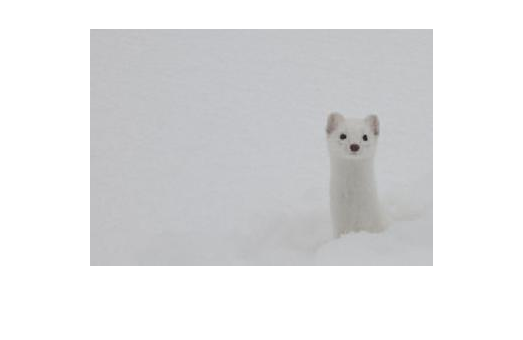

snow = imread("./images/snow.jpg"); 
imshow(snow)

## Task 1

This animal is camouflaged in the snow. In this practice, you will segment it using the difference in texture between the snow and the fur.

snow = im2gray(snow);

## Task 2

For comparison, you will first create filtered images using the standard deviation and range filters.

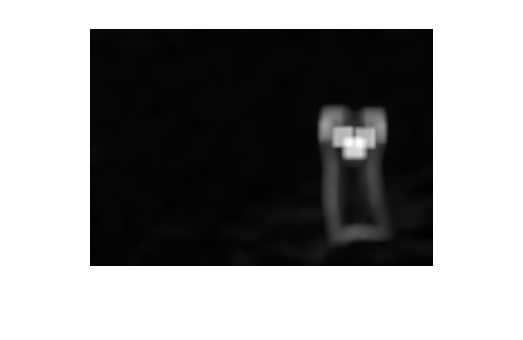

nHood = true(19);
snowSTD = stdfilt(snow, nHood);
snowSTD = rescale(snowSTD);
imshow(snowSTD)

## Task 3

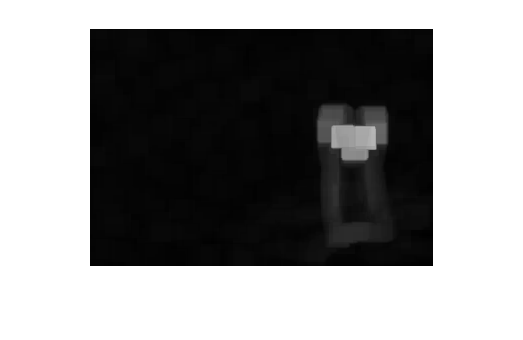

snowRNG = rangefilt(snow, nHood);
imshow(snowRNG)

## Task 4

Notice that the range and standard deviation filters picked up similar features of the animal—the eyes and outline. That is because both of these filters look at how much the pixels are changing in a neighborhood.

The entropy filter, in contrast, looks for patterns, or lack of patterns.

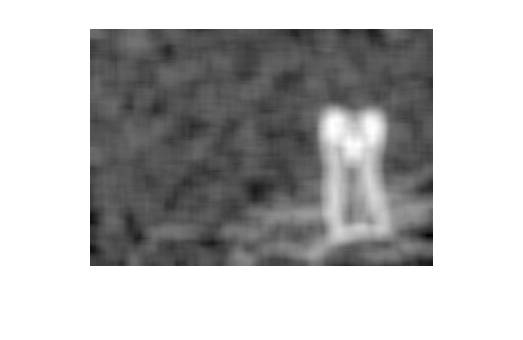

snowENT = entropyfilt(snow, nHood);
snowENT = rescale(snowENT);
imshow(snowENT)